# Frenet-Serret Frame

The other modlues in this series are

[**Introduction**](matlab:open('./Introduction.mlx'))**: **An interactive lesson on the definition of parametric equations, frames, and group transformations, all from the point of view of curves and trajectories as vector-valued parametric functions.

[**Natural Frenet frame**](matlab:open('./Natural_Frenet_Frames.mlx'))**: **An interactive lesson on the natural Frenet frame, where its similarities and differences with the Frenet-Serret frame are compared.

[**Affine frame**](matlab:open('./Affine_Frame.mlx'))**: **An interactive lesson on the equi-affine frame for 2-D as well as 3-D curves, defining concepts such as affine arc-length and affine curvature.

**Before you get started:**

- This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane. 

- The plots at each section of this Live Script are built upon variables that might be created in the previous sections. To get the intended visuals and results, run the sections consecutively.  

 
clc; clear all;

## Defining the Frenet-Serret Frame

Consider a curve $r(t)$ in $\mathbb{R}^3$ starting at $r(t_0) = r_0$. 

Ex. 

flag = "Viviani Curve";  

     *Note*: Click on the figure after visulization to see the options to change the view (rotate, pan, zoom).

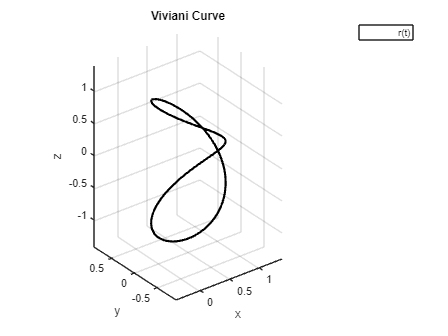

N = 200;
t = linspace(0,2,N);
dt = (t(end)-t(1))/(N-1);
% Defining the curves chosen by the user
switch flag
    case "Bezier Curve"
        Pts = [0 1 1 2;
               0 randi(5)-2 randi(5)-3 0;
               0 1 2  3];
        Curv = Bezier(Pts, t);
    case "Helix"
        x = cos(pi.*t);
        y = sin(pi.*t);
        z = t;
        Curv = [x; y; z];
    case "Viviani Curve"
        x = cos(pi.*t).^2;
        y = cos(pi.*t).*sin(pi.*t);
        z = sin(pi.*t);
        Curv = [x; y; z];
    case "Torus Knot"
        x = 1/3*(cos(pi.*t) + 2*cos(2*pi.*t));
        y = 1/3*(sin(pi.*t) - 2*sin(2*pi.*t));
        z = 1/3*(2*sin(pi.*t));
        Curv = [x; y; z];
end

% Plotting the curve
figure
plot3(Curv(1,:),Curv(2,:),Curv(3,:), 'k','LineWidth',2)
grid on
axis equal
ax = gca;
quiverSize = max([range(ax.XLim) range(ax.YLim) range(ax.ZLim)])/5;
[XLim, YLim, ZLim] = padax(ax, quiverSize, 1);
ax.XLim = XLim;
ax.YLim = YLim;
ax.ZLim = ZLim;

title(flag)
xlabel("x")
ylabel("y")
zlabel("z")
legend("r(t)")

Let $r(s)$ be the arc-length parameterization of $r(t)$, which we can rigorously define using 

            $s(t) = \int_{t_0}^{t} ||\dot{r}(\sigma)||d\sigma$. 

     *Note*: we will use $\dot{r}(t)$ to denote $\frac{dr}{dt}$, and $r'(t)$ to denote $\frac{dr}{ds}$.

We can define a *tangent*  at each point of the reparametrized curve $r(s)$ as

            
$$T(s) := \frac{dr}{ds} = \frac{dr}{dt} \div \frac{ds}{dt}$$
 

Observe that 

            
$$||T(s)|| = \frac{\left|\left| \frac{dr}{dt}\right| \right|}{\left|\frac{ds}{dt}\right|} =  \frac{\left|\frac{ds}{dt}\right|}{\left|\frac{ds}{dt}\right|} = 1 \ \ \ \ \ \forall \ s \ge 0$$
 

That is, trajectories under arc-length parametrization will always have unit speed. Thus we sometimes refer to the parameterization as the unit speed parameterization, and the tangent as the unit tangent. Imagine an ant crawling along the curve at constant speed. The tangent can be thought of as the direction the ant looks towards at any point of the curve represented by a unit vector.      

                               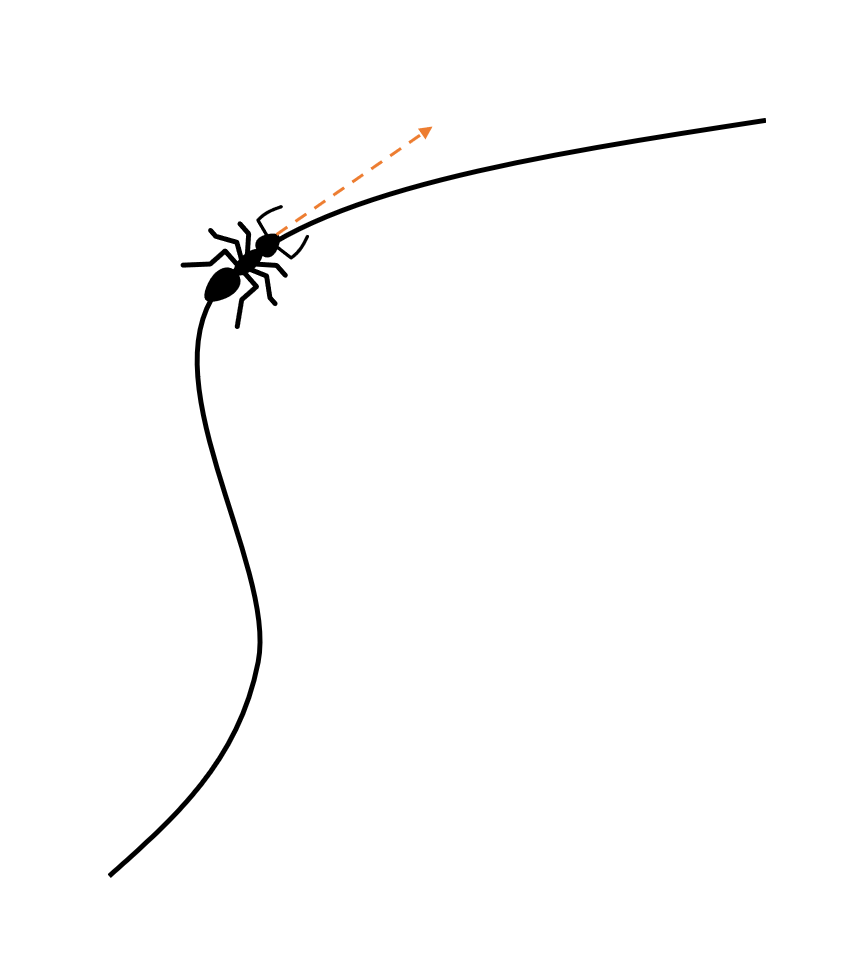

An important property of the arc-length $s(t)$ is the fact that it is *invariant *under change in coordinates by rotation and translation, i.e. $SE(3)$ transformations: Let $ \tilde{r}(t) = A r(t)+b$, where $A\in SO(3)$ and $b\in \mathbb{R}^3$. Then 

        
$$\tilde{s}(t) = \int_{t_{0}}^t||\dot{\tilde{r}}(\sigma)||d\sigma = \int_{t_{0}}^t||A\dot{r}(\sigma)||d\sigma = \int_{t_{0}}^t||\dot{r}(\sigma)||d\sigma = s(t)$$


We wish to find similar invariants of the curve.

The *classical curvature* of the curve is defined as 

            
$$\kappa (s) := \left|\left|\frac{dT}{ds}\right|\right|$$


 Then we can define the unit *normal* vector

            
$$N(s) = \frac{T'(s)}{\kappa(s)}$$


and the unit *binormal vector* 

            
$$B(s) = T(s) \times N(s)$$


The triplet $(T(s), N(s), B(s))$ gives us the *Frenet-Serret frame* of a curve in $\mathbb{R}^3$. See below for an example of the three frames for the example curve generated above:

Note: If the animations are causing slowdowns or not working correctly, uncheck the "animation" box for a simplified view of the visualization.

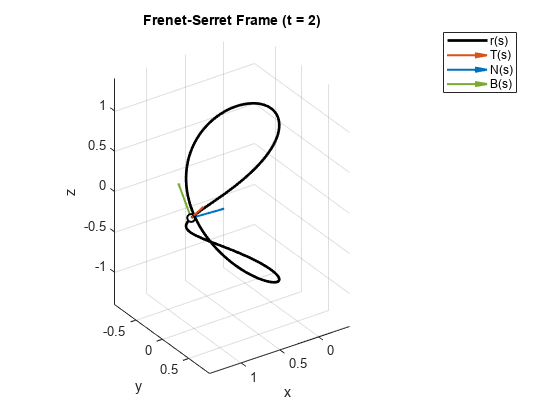

aFlag = true;  
% Finding the Frenet-Serret frame of the curve above
x = Curv(1, :);
y = Curv(2, :);
z = Curv(3, :);

r_dot = [gradient(x); gradient(y); gradient(z)]/dt;
s_dot = vecnorm(r_dot);
T = r_dot./s_dot;
dT = [gradient(T(1, :)); gradient(T(2, :)); gradient(T(3, :))]./s_dot;
Normal = dT./vecnorm(dT);
B = cross(T,Normal);

% Drawing curve and initial frame
figure
plot3(Curv(1,:),Curv(2,:),Curv(3,:),'k','LineWidth',2)
hold on
qT = quiver3(x(1), y(1), z(1), T(1, 1), T(2, 1), T(3, 1), quiverSize ,'SeriesIndex', 2, 'LineWidth',1.5);
qN = quiver3(x(1), y(1), z(1), Normal(1, 1), Normal(2, 1), Normal(3, 1), quiverSize ,'SeriesIndex', 1, 'LineWidth',1.5);
qB = quiver3(x(1), y(1), z(1), B(1, 1), B(2, 1), B(3, 1), quiverSize ,'SeriesIndex', 5, 'LineWidth',1.5);
qU = quiver3(x(1), y(1), z(1), 0, 0, 0, 'o', 'LineWidth',1.5, 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'w');
axis equal
ax = gca;
[XLim, YLim, ZLim] = padax(ax, quiverSize, 1);
ax.XLim = XLim;
ax.YLim = YLim;
ax.ZLim = ZLim;
grid on
xlabel('x')
ylabel('y')
zlabel('z')
legend(["r(s)","T(s)","N(s)","B(s)"])

% Animate
if aFlag
    for i=1:length(t)-2
      time = round(t(i)*10)/10;
      title(['Frenet-Serret Frame (t = ' num2str(time) ')'])
      ax.View = [-32.5+180*i/length(t), 30];

      qT.XData = x(i);
      qT.YData = y(i);
      qT.ZData = z(i);
      qT.UData = T(1, i);
      qT.VData = T(2, i);
      qT.WData = T(3, i);

      qN.XData = x(i);
      qN.YData = y(i);
      qN.ZData = z(i);
      qN.UData = Normal(1, i);
      qN.VData = Normal(2, i);
      qN.WData = Normal(3, i);

      qB.XData = x(i);
      qB.YData = y(i);
      qB.ZData = z(i);
      qB.UData = B(1, i);
      qB.VData = B(2, i);
      qB.WData = B(3, i);

      qU.XData = x(i);
      qU.YData = y(i);
      qU.ZData = z(i);
      qU.UData = 0;
      qU.VData = 0;
      qU.WData = 0;
      
      drawnow 
      
    end
end
hold off

There is a hidden assumption underlying these definitions: that $\kappa(s) \neq 0 $ for all $s$ (i.e. the curve is not a straight line). We call this condition *non-degeneracy*. (We will see later on what happens when this condition is not held). 

The *torsion* of the curve $\tau(s)$ is defined as 

        
$$\tau(s) = -\frac{dB}{ds}\cdot N(s)$$


Similar to the arc-length $s(t)$, the curvature $\kappa$ and torsion $\tau$ of the curve are invariant under $SE(3)$ transformations (rotations and translations). Additionally, the two invariants $\kappa$ and $\tau$ uniquely define any given curve in $\mathbb{R}^3
$ up to SE(3) actions.  For curves in $\mathbb{R}^2$, $\tau(s)\equiv 0$, so the curve is uniquely determined by its curvature $\kappa$. Here's what the curvature and torsion of the curve above looks like:

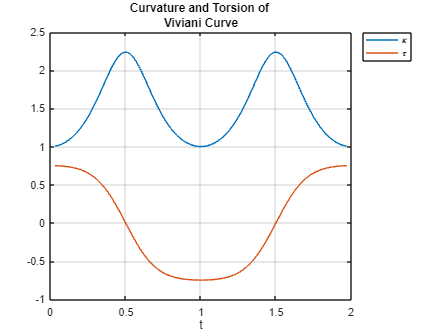

% Calculating curvature and torsion
r_ddot = [gradient(r_dot(1,:)); gradient(r_dot(2,:)); gradient(r_dot(3,:))]/dt;
kappa = vecnorm(cross(r_dot, r_ddot))./vecnorm(r_dot).^3;
r_dddot = [gradient(r_ddot(1,:)); gradient(r_ddot(2,:)); gradient(r_ddot(3,:))]/dt;
tau = dot(cross(r_dot, r_ddot), r_dddot) ./ vecnorm(cross(r_dot, r_ddot)).^2;

% Plot
plot(t(4:end-3), kappa(4:end-3), t(4:end-3), tau(4:end-3))
grid on
xlabel('t')
legend(["\kappa","\tau"])
title(['Curvature and Torsion of ' flag])

Next, we discuss some applications of the Frenet-Serret frame to a specific dynamical model.

## Planar two-link Manipulator

Consider the two-link planar manipulator shown below:

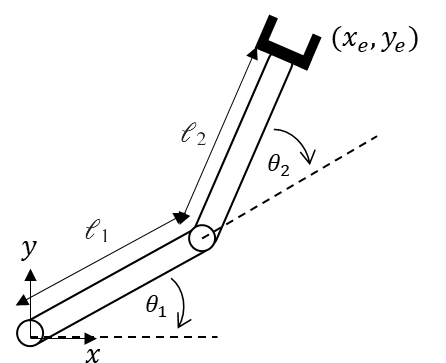

where each link is a rectangular bar with mass $m_i$ and mome

nt of inertia tensor $I_i = \pmatrix{I_{x_i} & 0 & 0 \cr 0 & I_{y_i} & 0 \cr 0 & 0 & I_{z_i}}$. We can derive the equation of motion for the two angles $\theta_1$ and $\theta_2$ using Euler-Lagrange equations, and after a few calculations arrive at:

            
$$\pmatrix{\alpha + 2\beta \cos(\theta_2) & \gamma +\beta \cos(\theta_2) \cr \gamma + \beta \cos(\theta_2) & \gamma}\pmatrix{\ddot{\theta}_1\cr \ddot{\theta}_2} + \pmatrix{-\beta \sin(\theta_2) \dot{\theta}_2 & -\beta \sin(\theta_2)(\dot{\theta}_1+\dot{\theta}_2) \cr \beta \sin(\theta_2) \dot{\theta_1} & 0} \pmatrix{\dot{\theta}_1 \cr \dot{\theta}_2} = \pmatrix{u_1 \cr u_2}$$


Here 

            
$$\alpha = I_{z_1}+I_{z_2}+\frac{1}{4}m_1 \ell_2^2 + m_2(\ell_1^2+\frac{1}{4}\ell_2^2)$$


            
$$\beta = \frac{1}{2}m_2\ell_1\ell_2$$


            
$$\gamma = I_{z_2}+\frac{1}{4}m_2\ell_2^2$$
 

and $u_1$ and $u_2$ are the applied torques to the two segments of the manipulator respectively. 

After solving the equation of motion for $\theta_1$ and $\theta_2$, we can calculate the position of the end effector $(x_e, y_e)$ using 

        
$$x_e = \ell_1\cos(\theta_1) + \ell_2\cos(\theta_1+\theta_2)$$


        
$$y_e = \ell_1\sin(\theta_1) + \ell_2\sin(\theta_1+\theta_2)$$


Here's what the movement of the manipulator looks like if you give the first link a "kick". Note that friction and other damping forces are ignored.

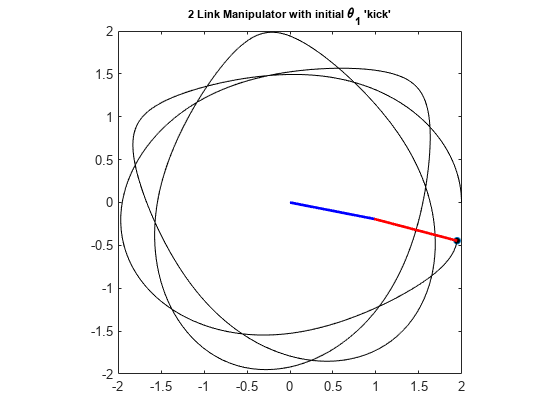

%declaring constants
 
m1 = 1;
m2 = 1;
L1 = 1;
L2 = 1;
C = [m1; m2; L1; L2];

%solving eq. of motion
u1 = @(t) 10*(t<.5)+0*(t>.5);
u2 = @(t) 5*(t<.5)+0*(t>.5);
tspan = linspace(0, 10, 500);
x0 = [0; 0; 0; 0];
[t, xvec] = tlinkmanipode(C, u1, u2, tspan, x0);
theta1 = xvec(:, 1);
theta2 = xvec(:, 2);

%end effector position
x_m1 = L1*cos(theta1);
y_m1 = L1*sin(theta1);

xe = L1*cos(theta1) + L2*cos(theta1+theta2);
ye = L1*sin(theta1) + L2*sin(theta1+theta2);

%plot
trail = zeros(2, length(t))+[xe(1); ye(1)];
p1 = plot(xe(1), ye(1), 'o','MarkerSize',5, 'MarkerFaceColor', 'k');
hold on
p2 = plot(trail(1,:), trail(2,:), 'k');
link1 = line([0 x_m1(1)],[0 y_m1(1)],'Color','b', 'LineWidth', 2);
link2 = line([x_m1(1) xe(1)],[y_m1(1) ye(1)],'Color','r', 'LineWidth', 2);
    title("2 Link Manipulator with initial \theta_1 'kick'")
    axis equal
    axis([-L1-L2 L1+L2 -L1-L2 L1+L2])
    hold off
for k = 1:length(t)
    p1.XData = xe(k);
    p1.YData = ye(k);
    p2.XData(1:(length(t)-k+1)) = xe(k);
    p2.YData(1:(length(t)-k+1)) = ye(k);

    link1.XData = [0 x_m1(k)];
    link1.YData = [0 y_m1(k)];
    link2.XData = [x_m1(k) xe(k)];
    link2.YData = [y_m1(k) ye(k)];
    
    drawnow
end

Another way to represent the location of the end effector is through the two angles $\theta_1$ and $\theta_2$ directly. Since $\theta_1, \theta_2 \in [0, 2\pi]$, the shape space of $(\theta_1, \theta_2)$ can be represented by $S^1 \times S^1$, or in other words a torus. The trajectory of the end effector in $\mathbb{R}^2$ can then be seens as trajectories on the surface of this torus. We can also correspondingly calculate the Frenet-Serret frame of the curve on the toroidal surface.

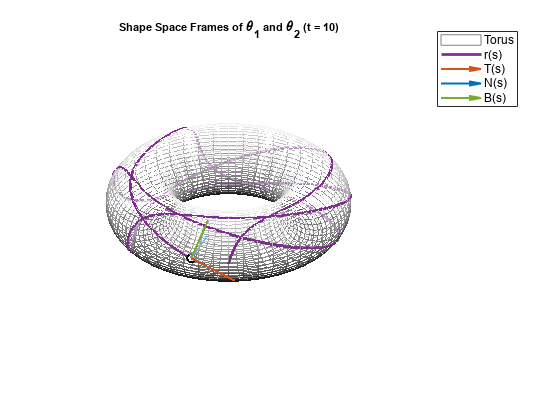

%plotting torus
 
figure
theta = 2*pi*(0:50)/50;
phi   = 2*pi*(0:50)'/50;
x = (2.5 + 1*cos(phi))*cos(theta);
y = (2.5 + 1*cos(phi))*sin(theta);
z = 1*sin(phi)*ones(size(theta));
mesh(x,y,z, 'FaceAlpha', .45)
colormap(gray)
hold on

%finding Frenet-Serret frame
Cx = (2.5 + 1*cos(theta2)).*cos(theta1);
Cy = (2.5 + 1*cos(theta2)).*sin(theta1);
Cz = 1*sin(theta2).*ones(size(theta1));
r_dot = [gradient(Cx)'; gradient(Cy)'; gradient(Cz)']/dt;
s_dot = vecnorm(r_dot);
T = r_dot./s_dot;
dT = [gradient(T(1, :)); gradient(T(2, :)); gradient(T(3, :))]./s_dot;
Normal = dT./vecnorm(dT);
B = cross(T,Normal);

%plot
plot3(Cx, Cy, Cz, 'Color', '#7E2F8E', LineWidth=2)
axis equal
ax = gca;
quiverSize = max([range(ax.XLim) range(ax.YLim) range(ax.ZLim)])/5;
[XLim, YLim, ZLim] = padax(ax, quiverSize, 1);
ax.XLim = XLim;
ax.YLim = YLim;
ax.ZLim = ZLim;
axis off

qT = quiver3(Cx(1), Cy(1), Cz(1), T(1, 1), T(2, 1), T(3, 1), quiverSize ,'SeriesIndex', 2, 'LineWidth',1.5);
qN = quiver3(Cx(1), Cy(1), Cz(1), Normal(1, 1), Normal(2, 1), Normal(3, 1), quiverSize ,'SeriesIndex', 1, 'LineWidth',1.5);
qB = quiver3(Cx(1), Cy(1), Cz(1), B(1, 1), B(2, 1), B(3, 1), quiverSize ,'SeriesIndex', 5, 'LineWidth',1.5);
qU = quiver3(Cx(1), Cy(1), Cz(1), 0, 0, 0, 'o', 'LineWidth',1.5, 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'w');


legend(['Torus', "r(s)","T(s)","N(s)","B(s)"])

% Animate
for i=1:length(t)-2
  time = round(t(i)*10)/10;
  title(['Shape Space Frames of \theta_1 and \theta_2 (t = ' num2str(time) ')'])
  ax.View = [90, 30];

  qT.XData = Cx(i);
  qT.YData = Cy(i);
  qT.ZData = Cz(i);
  qT.UData = T(1, i);
  qT.VData = T(2, i);
  qT.WData = T(3, i);

  qN.XData = Cx(i);
  qN.YData = Cy(i);
  qN.ZData = Cz(i);
  qN.UData = Normal(1, i);
  qN.VData = Normal(2, i);
  qN.WData = Normal(3, i);

  qB.XData = Cx(i);
  qB.YData = Cy(i);
  qB.ZData = Cz(i);
  qB.UData = B(1, i);
  qB.VData = B(2, i);
  qB.WData = B(3, i);

  qU.XData = Cx(i);
  qU.YData = Cy(i);
  qU.ZData = Cz(i);
  qU.UData = 0;
  qU.VData = 0;
  qU.WData = 0;
  
  drawnow 
  
end

hold off

Here are some shapes produced by the end effector and their corresponding trajectories on the shape space torus:

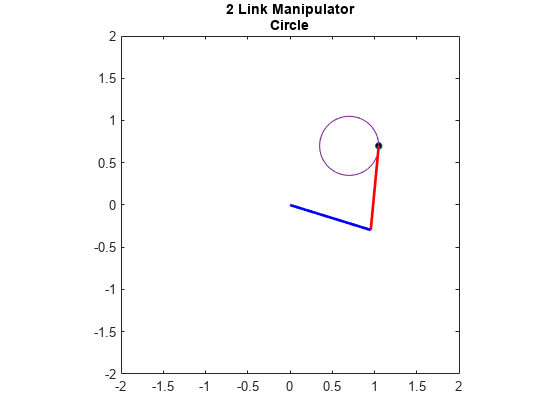

aFlag = true; 
flag = "Circle";
 
t = linspace(0, 5, 200);
switch flag
    case 'Circle'
        x = L1*.7/2*cos(2*pi*t)+L1*.7;
        y = L1*.7/2*sin(2*pi*t)+L1*.7;
    case 'Ellipse'
        x = (L1+L2)*cos(2*pi*t);
        y = (L1+L2)/2*sin(2*pi*t);
    case 'Lemniscate'
        x = L1*cos(2*pi*t)./(1+sin(2*pi*t).^2);
        y = L1*cos(2*pi*t).*sin(2*pi*t)./(1+sin(2*pi*t).^2);
end

%inverse kinematics (2 possible solutions, we will use the positive one)
c2 = (x.^2+y.^2-(L1^2+L2^2))/(2*L1*L2);

s2P = sqrt(1-c2.^2);
s2N = -sqrt(1-c2.^2);

theta2N = atan2(s2N, c2);
theta2P = atan2(s2P, c2);

denomN = L1^2+L2^2+2*L1*L2*cos(theta2N);
denomP = L1^2+L2^2+2*L1*L2*cos(theta2P);
theta1N = atan2((L1*y-L2*x.*sin(theta2N)+L2*y.*cos(theta2N))./denomN, (L1*x+L2*y.*sin(theta2N)+L2*x.*cos(theta2N))./denomN);
theta1P = atan2((L1*y-L2*x.*sin(theta2P)+L2*y.*cos(theta2P))./denomP, (L1*x+L2*y.*sin(theta2P)+L2*x.*cos(theta2P))./denomP);

xeN = L1*cos(theta1N) + L2*cos(theta1N+theta2N);
yeN = L1*sin(theta1N) + L2*sin(theta1N+theta2N);

xeP = L1*cos(theta1P) + L2*cos(theta1P+theta2P);
yeP = L1*sin(theta1P) + L2*sin(theta1P+theta2P);

xe = xeP;
ye = yeP;

theta1 = theta1P;
theta2 = theta2P;

%end effector position
x_m1 = L1*cos(theta1);
y_m1 = L1*sin(theta1);

%plot
trail = zeros(2, length(t))+[xe(1); ye(1)];
p1 = plot(xe(1), ye(1), 'o','MarkerSize',5, 'MarkerFaceColor', 'k');
hold on
p2 = plot(trail(1,:), trail(2,:), 'Color', '#7E2F8E', LineWidth=1);
link1 = line([0 x_m1(1)],[0 y_m1(1)],'Color','b', 'LineWidth', 2);
link2 = line([x_m1(1) xe(1)],[y_m1(1) ye(1)],'Color','r', 'LineWidth', 2);
title(["2 Link Manipulator" flag])
axis equal
axis([-L1-L2 L1+L2 -L1-L2 L1+L2])
hold off
if aFlag
    for k = 1:length(t)
        p1.XData = xe(k);
        p1.YData = ye(k);
        p2.XData(1:(length(t)-k+1)) = xe(k);
        p2.YData(1:(length(t)-k+1)) = ye(k);
    
        link1.XData = [0 x_m1(k)];
        link1.YData = [0 y_m1(k)];
        link2.XData = [x_m1(k) xe(k)];
        link2.YData = [y_m1(k) ye(k)];
        
        drawnow
    end
end

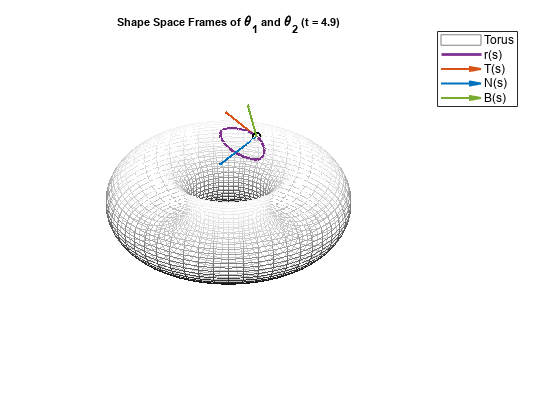

 
%plotting torus
figure
theta = 2*pi*(0:50)/50;
phi   = 2*pi*(0:50)'/50;
x = (2 + 1*cos(phi))*cos(theta);
y = (2 + 1*cos(phi))*sin(theta);
z = 1*sin(phi)*ones(size(theta));
mesh(x,y,z, 'FaceAlpha', .75)
colormap(gray)
hold on

%calculating frames
theta1 = theta1P';
theta2 = theta2P';
Cx = (2 + 1*cos(theta2)).*cos(theta1);
Cy = (2 + 1*cos(theta2)).*sin(theta1);
Cz = 1*sin(theta2).*ones(size(theta1));
r_dot = [gradient(Cx)'; gradient(Cy)'; gradient(Cz)'];
s_dot = vecnorm(r_dot);
T = r_dot./s_dot;
dT = [gradient(T(1, :)); gradient(T(2, :)); gradient(T(3, :))]./s_dot;
Normal = dT./vecnorm(dT);
B = cross(T,Normal);

%drawing initial frames
plot3(Cx, Cy, Cz, 'Color', '#7E2F8E', LineWidth=2)
axis equal
ax = gca;
quiverSize = max([range(ax.XLim) range(ax.YLim) range(ax.ZLim)])/5;
[XLim, YLim, ZLim] = padax(ax, quiverSize, 1);
ax.XLim = XLim;
ax.YLim = YLim;
ax.ZLim = ZLim;
axis off

qT = quiver3(Cx(1), Cy(1), Cz(1), T(1, 1), T(2, 1), T(3, 1), quiverSize ,'SeriesIndex', 2, 'LineWidth',1.5);
qN = quiver3(Cx(1), Cy(1), Cz(1), Normal(1, 1), Normal(2, 1), Normal(3, 1), quiverSize ,'SeriesIndex', 1, 'LineWidth',1.5);
qB = quiver3(Cx(1), Cy(1), Cz(1), B(1, 1), B(2, 1), B(3, 1), quiverSize ,'SeriesIndex', 5, 'LineWidth',1.5);
qU = quiver3(Cx(1), Cy(1), Cz(1), 0, 0, 0, 'o', 'LineWidth',1.5, 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'w');


legend(['Torus', "r(s)","T(s)","N(s)","B(s)"])

% Animate
if aFlag
    for i=1:length(t)-2
      time = round(t(i)*10)/10;
      title(['Shape Space Frames of \theta_1 and \theta_2 (t = ' num2str(time) ')'])
      ax.View = [-90, 30];
    
      qT.XData = Cx(i);
      qT.YData = Cy(i);
      qT.ZData = Cz(i);
      qT.UData = T(1, i);
      qT.VData = T(2, i);
      qT.WData = T(3, i);
    
      qN.XData = Cx(i);
      qN.YData = Cy(i);
      qN.ZData = Cz(i);
      qN.UData = Normal(1, i);
      qN.VData = Normal(2, i);
      qN.WData = Normal(3, i);
    
      qB.XData = Cx(i);
      qB.YData = Cy(i);
      qB.ZData = Cz(i);
      qB.UData = B(1, i);
      qB.VData = B(2, i);
      qB.WData = B(3, i);
    
      qU.XData = Cx(i);
      qU.YData = Cy(i);
      qU.ZData = Cz(i);
      qU.UData = 0;
      qU.VData = 0;
      qU.WData = 0;
      
      drawnow 
      
    end
end
hold off

Did you catch what happened at $(x_e, y_e) = (0, 0)$ for the lemniscate? When solving for the inverse kinematics for the 2-link manipulator (i.e. finding $(\theta_1, \theta_2)$ from $(x_e, y_e)$), that point is what we call a singularity, meaning there are infinite solutions for $(\theta_1, \theta_2)$ at that point. 

 *Think about the benefits of solving inverse kinematics for the 2 link manipulator in the torus shape space instead of the 2-D plane. *

## Unicycle Model

Consider a person riding a unicycle. We can denote their position on the ground as $(x(t), y(t))
$ and the direction they face as $\theta(t)$.  At any point in time, they can pedal forwards or backwards on the unicycle, or they can turn the wheel on the spot. We can model these two motions with a velocity $v(t)$ and an angular velocity $\omega(t)$, respectively, with the added restriction that $v$ can only move in the direction of $\theta$.

 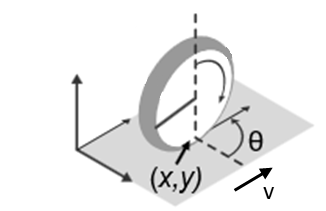

We can then write a system of differential equations that model the trajectory of the unicycle involving the variables denoted above:

            
$$\dot{x} = v\cos(\theta)\\
\dot{y} = v\sin(\theta)\\
\dot{\theta} = \omega$$


For example, suppose $v(t) $ and $\omega(t)$ are both constant at $2 \ m/s $ and $2 \ rad/s$ respectively. The corresponding trajectory will look as follows (including a look at the Tangent and Normal vector of the Frenet-Serret frame for trajectory):

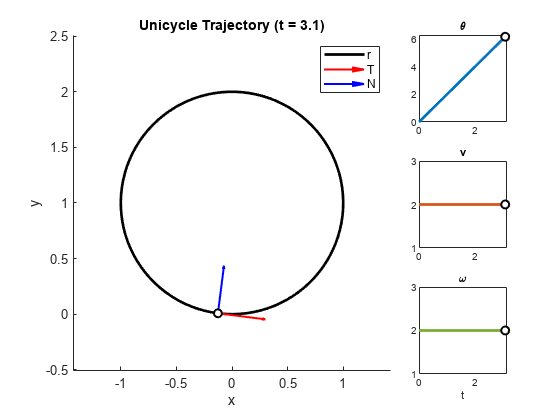

  
aFlag = true;
%generate trajectory of unicycle
T = pi; 
N = 100;
v = @(s) 2;
w = @(s) 2;
tspan = linspace(0, T, N);
x0 = [0 0 0];
[t, xvec] = unicycleode(v, w, tspan, x0);
x = xvec(:, 1);
y = xvec(:, 2);
theta = xvec(:, 3);

%calculating frames
r_dot = [gradient(x)'; gradient(y)'];
s_dot = vecnorm(r_dot);
T = r_dot./s_dot;
dT = [gradient(T(1, :)); gradient(T(2, :))]./s_dot;
dT(abs(dT)<1e-4) = 0;
Normal = dT./vecnorm(dT);

% convert from function handle to vector
vel = zeros(1, length(t));
omeg = zeros(1, length(t));
for i = 1:length(t)
    vel(i) = v(t(i));
    omeg(i) = w(t(i));
end

%plot
figure
sub1 = subplot(3, 4, [1, 2, 3, 5, 6, 7, 9, 10, 11]);
hold on;
cla(sub1);
plot(x, y, 'Color', 'k', 'LineWidth', 2)
axis equal
ax = gca;
quiverSize = max([range(ax.XLim) range(ax.YLim)])/5;
[XLim, YLim, ~] = padax(ax, quiverSize, 0);
ax.XLim = XLim;
ax.YLim = YLim;

title('Unicycle Trajectory')
xlabel('x')
ylabel('y')

sub2 = subplot(3, 4, 4);
cla(sub2);
axis(sub2, [floor(min(t)), ceil(max(t)), floor(min(theta)), ceil(max(theta))]);
plot(t, theta, 'SeriesIndex', 1, 'LineWidth', 2)
title('\theta')
hold on

sub3 = subplot(3, 4, 8);
cla(sub3);
axis(sub3, [floor(min(t)), ceil(max(t)), floor(min(vel))-1, ceil(max(vel))+1]);
plot(t, vel, 'SeriesIndex', 2, 'LineWidth', 2);
title('v')
hold on

sub4 = subplot(3, 4, 12);
cla(sub4);
axis(sub4, [floor(min(t)), ceil(max(t)), floor(min(omeg))-1, ceil(max(omeg))+1])
plot(t, omeg, 'SeriesIndex', 5, 'LineWidth', 2);
title('\omega')
xlabel('t')
hold on

qT = quiver(sub1, x(2), y(2), T(1, 1), T(2, 1), quiverSize ,'r', 'LineWidth',1.5);
qN = quiver(sub1, x(2), y(2), Normal(1, 1), Normal(2, 1), quiverSize ,'b', 'LineWidth',1.5);
qU = quiver(sub1, x(2), y(2), 0, 0, 'o', 'LineWidth',1.5, 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'w');
qTheta = quiver(sub2, t(2), theta(2), 0, 0, 'o', 'LineWidth',1.5, 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'w');
qVel = quiver(sub3, t(2), vel(2), 0, 0, 'o', 'LineWidth',1.5, 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'w');
qOmeg = quiver(sub4, t(2), omeg(2), 0, 0, 'o', 'LineWidth',1.5, 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'w');

legend(sub1, ["r","T","N"])

% Animate
if aFlag
    for i=1:length(t)-2
      time = round(t(i)*10)/10;
      title(sub1, ['Unicycle Trajectory (t = ' num2str(time) ')'])

      qT.XData = x(i);
      qT.YData = y(i);
      qT.UData = T(1, i);
      qT.VData = T(2, i);

      qN.XData = x(i);
      qN.YData = y(i);
      qN.UData = Normal(1, i);
      qN.VData = Normal(2, i);

      qU.XData = x(i);
      qU.YData = y(i);
      qU.UData = 0;
      qU.VData = 0;

      qTheta.XData = t(i);
      qTheta.YData = theta(i);
      qTheta.UData = 0;
      qTheta.VData = 0;

      qVel.XData = t(i);
      qVel.YData = vel(i);
      qVel.UData = 0;
      qVel.VData = 0;

      qOmeg.XData = t(i);
      qOmeg.YData = omeg(i);
      qOmeg.UData = 0;
      qOmeg.VData = 0;

      drawnow
    end
end
hold off

Here are a few more examples of the unicycle's trajectories for various $v(t)$ and $\omega(t)$.

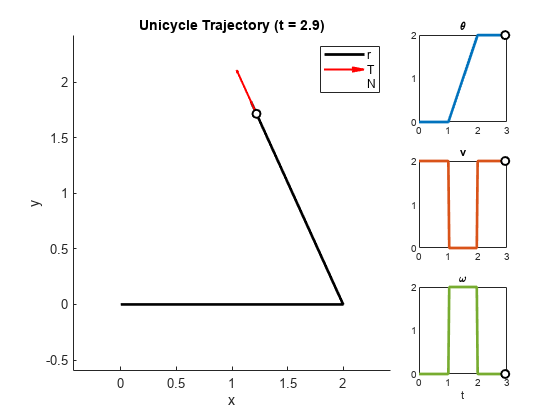

T = 3;
v = @(s) 2*(s<=T/3)+0*((s>T/3)&(s<2*T/3))+2*(s>=2*T/3); w = @(s) 0*(s<=T/3)+2*((s>T/3)&(s<2*T/3))+0*(s>=2*T/3);  

% generate unicycle trajectory from the selected control
tspan = linspace(0, T, 100);
x0 = [0 0 0];
[t, xvec] = unicycleode(v, w, tspan, x0);
x = xvec(:, 1);
y = xvec(:, 2);
theta = xvec(:, 3);

% find frames
r_dot = [gradient(x)'; gradient(y)'];
s_dot = vecnorm(r_dot);
T = r_dot./s_dot;
dT = [gradient(T(1, :)); gradient(T(2, :))]./s_dot;
dT(abs(dT)<1e-4) = 0; %sanitize underflows
Normal = dT./vecnorm(dT);

% convert from function handle to vector
vel = zeros(1, length(t));
omeg = zeros(1, length(t));
for i = 1:length(t)
    vel(i) = v(t(i));
    omeg(i) = w(t(i));
end

%Plot
figure
sub1 = subplot(3, 4, [1, 2, 3, 5, 6, 7, 9, 10, 11]);
hold on;
cla(sub1);
plot(x, y, 'Color', 'k', 'LineWidth', 2)
axis equal
ax = gca;
quiverSize = max([range(ax.XLim) range(ax.YLim)])/5;
[XLim, YLim, ~] = padax(ax, quiverSize, 0);
ax.XLim = XLim;
ax.YLim = YLim;

title('Unicycle Trajectory')
xlabel('x')
ylabel('y')

sub2 = subplot(3, 4, 4);
cla(sub2);
axis(sub2, [floor(min(t)), ceil(max(t)), floor(min(theta)), ceil(max(theta))]);
plot(t, theta, 'SeriesIndex', 1, 'LineWidth', 2)
title('\theta')
hold on

sub3 = subplot(3, 4, 8);
cla(sub3);
axis(sub3, [floor(min(t)), ceil(max(t)), floor(min(vel))-1, ceil(max(vel))+1]);
plot(t, vel, 'SeriesIndex', 2, 'LineWidth', 2);
title('v')
hold on

sub4 = subplot(3, 4, 12);
cla(sub4);
axis(sub4, [floor(min(t)), ceil(max(t)), floor(min(omeg))-1, ceil(max(omeg))+1])
plot(t, omeg, 'SeriesIndex', 5, 'LineWidth', 2);
title('\omega')
xlabel('t')
hold on

qT = quiver(sub1, x(2), y(2), T(1, 1), T(2, 1), quiverSize ,'r', 'LineWidth',1.5);
qN = quiver(sub1, x(2), y(2), Normal(1, 1), Normal(2, 1), quiverSize ,'b', 'LineWidth',1.5);
qU = quiver(sub1, x(2), y(2), 0, 0, 'o', 'LineWidth',1.5, 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'w');
qTheta = quiver(sub2, t(2), theta(2), 0, 0, 'o', 'LineWidth',1.5, 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'w');
qVel = quiver(sub3, t(2), vel(2), 0, 0, 'o', 'LineWidth',1.5, 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'w');
qOmeg = quiver(sub4, t(2), omeg(2), 0, 0, 'o', 'LineWidth',1.5, 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'w');

legend(sub1, ["r","T","N"])

% animate
if aFlag
    for i=1:length(t)-2
      time = round(t(i)*10)/10;
      title(sub1, ['Unicycle Trajectory (t = ' num2str(time) ')'])

      qT.XData = x(i);
      qT.YData = y(i);
      qT.UData = T(1, i);
      qT.VData = T(2, i);

      qN.XData = x(i);
      qN.YData = y(i);
      qN.UData = Normal(1, i);
      qN.VData = Normal(2, i);

      qU.XData = x(i);
      qU.YData = y(i);
      qU.UData = 0;
      qU.VData = 0;

      qTheta.XData = t(i);
      qTheta.YData = theta(i);
      qTheta.UData = 0;
      qTheta.VData = 0;

      qVel.XData = t(i);
      qVel.YData = vel(i);
      qVel.UData = 0;
      qVel.VData = 0;

      qOmeg.XData = t(i);
      qOmeg.YData = omeg(i);
      qOmeg.UData = 0;
      qOmeg.VData = 0;

      drawnow
    end
end
hold off

Note how many of the trajectories have points or segments where the curvature $\kappa$ = 0. In the 2-D plane, there are only two possible choices for the normal given a tangent vector. Thus we can define the normal by choosing one of the two possibile choices, similar to choosing a sign convention. We will be taking a look in the next module at a moving frame that allows degeneracy, called the [*Natural Frenet Frame*](matlab: edit Natural_Frenet_Frames.mlx)*.*

### Unicycle model using Frenet-Serret Frame

Let $r(t) $ be the trajectory of the unicycle on the 2-D plane. Then the Frenet-Serret frame for that trajectory will be

        
$$T(s) = \frac{\dot{r}}{||\dot{r}||} = [\cos(\theta),\ \sin(\theta)]$$


        
$$N(s) = \frac{T'}{||T'||} = [-\sin(\theta),\ \cos(\theta)]$$


        *Note*: This is actually the case for any regular curve in 2-D if we write $\theta$ as the angle of the tangent vector. (Why is that the case?)

If we setup the frames and $r(t)$ into a 3x3 square matrix, we see that the configuration of the unicycle can be represented as an element of the matrix Lie group $SE(2)$.

        
$$\pmatrix{T & N& r(t)  \cr 0 & 0 & 1}  = \pmatrix{\cos(\theta)  & -\sin(\theta) & x  \cr\sin(\theta) & \cos(\theta) & y \cr 0& 0& 1} $$


The unicycle dynamics then can be modeled as dynamics on the Lie group $SE(2)$. For $g(t) \in SE(2)$, 

        
$$\dot{g}(t) = g(t)\xi(v, \omega)$$


where 

        
$$\xi = \pmatrix{0 & -\omega & v \cr \omega & 0 & 0& \cr 0 & 0 & 0}$$


In the next module, [**Natural Frenet frame**](matlab:open('./Natural_Frenet_Frames.mlx')) is introduced its similarities and differences with the Frenet-Serret frame are discussed.

## Practice Problems

- Calculate the Frenet-Serret frame for the curve $r(t) = [\sin(t),\  \sin(t),\ \cos(t)]  $ in  for any $t$ (i.e. find $[ T\ N\ B]$). 

- Calculate and plot the curvature $\kappa(t)$ and torsion $\tau(t)$ of the curve $r(t) = [t+\cos(t),\ t- \sin(t),\ t]$ using MATLAB's Symbolic Toolbox.

- For points that are not singularities, solving for the inverse kinematics of a 2-link manipulator will give you two solutions for $(\theta_1, \theta_2)$. What do these two solutions look like on the Torus shape space? Can you find the relationship between them?

- a) Consider the unicycle model 

                                   
$$\dot{x} = v\cos(\theta)\\
\dot{y} = v\sin(\theta)\\
\dot{\theta} = \omega$$
    

                   Let $u_1 = v\cos(\theta) $ and $u_2 = \omega$ be a change of variables. Find the dynamical model for the unicycle in terms of $u_1$ and $u_2$ (For simplicity use the small angle approximation $\tan(\theta) \approx \theta$)

             b) Let $u_1 = a\sin(\sigma t)$ and $u_2 = b\cos(\sigma  t)$. Based your answer from part (a), show that the unicycle moves from $[x,\ y,\ \theta] = [0,\ 0,\ 0] $ to $[x,\ y,\ \theta] = [0,\ \frac{ab}{\sigma^2},\ 0] $ after $\frac{2\pi}{\sigma}$ seconds following $u_1$ and $u_2$.

             c) Design a program for $v(t)$ and $\omega(t)$ such that the unicycle moves from $[x,\ y,\ \theta] = [0,\ 0,\ 0] $ to $[x,\ y,\ \theta] = [10,\ 10,\ 0] $ in 2 seconds.

## Citations

Clelland, Jeanne N. *From Frenet to Cartan: the method of moving frames*. Vol. 178. American Mathematical Soc., 2017.

Millman, Richard S., and George D. Parker. *Elements of differential geometry*. Prentice Hall, 1977.

## Helper Functions 

#### Bezier Curve

Bezier curve construction using points $\mathbf{P}_i
$, $i = 1, 2, ... , n$.

            
$$\mathbf{B}(t) = \sum_{i=0}^n {n\choose i } (1-t)^{n-i}t^{i}\mathbf{P}_i
$$


function B = Bezier(Pts,t)
    n = size(Pts,2)-1;
    for k = 1:length(t)
        B(:,k) = [0 0 0]';
        for i = 1:size(Pts,2)
            B(:,k) = B(:,k)+Pts(:,i)*nchoosek(n, i-1)*(1-t(k))^(n-i+1)*(t(k)^(i-1));
        end
    end
end

#### Two-link Manipulator

Finding the $\theta_i$'s of the system (forward kinematics)

function dxdt = odefunM(x, C, u1, u2) %x = [theta1; theta2; theta1_dot; theta2_dot]

    m1 = C(1);
    m2 = C(2);
    L1 = C(3);
    L2 = C(4);
    Iz1 = 1/3*m1*L1^2;
    Iz2 = 1/3*m2*L2^2;
    
    alpha = Iz1 + Iz2 + 1/4*m1*L2^2+m2*(L1^2+1/4*L2^2);
    beta = 1/2*m2*L1*L2;
    gamma = Iz2 + 1/4*m2*L2^2;
    
    theta1 = x(1);
    theta2 = x(2);
    dtheta1 = x(3);
    dtheta2 = x(4);

    A = [alpha + 2*beta*cos(theta2), gamma + beta*cos(theta2);
         gamma + beta*cos(theta2), gamma];
    B = [-beta*sin(theta2)*dtheta2, -beta*sin(theta2)*(dtheta1+dtheta2);
         beta*sin(theta2)*dtheta1, 0];
    M = [B, A; eye(2), zeros(2,2)]^-1; 
    dxdt = M*[u1; u2; dtheta1; dtheta2]; 
end

function [t, x] = tlinkmanipode(C, u1, u2, tspan, x0)
    [t, x] = ode45(@(t, x) odefunM(x, C, u1(t), u2(t)), tspan, x0);
end

#### Unicycle Kinematics

Finding the trajectory of the unicycle for a given set of controls.

%using ode45
function dxdt = odefunU(x, v, w) %x = [x; y; theta]
    dxdt = zeros(3,1);
    dxdt(1) = v*cos(x(3));
    dxdt(2) = v*sin(x(3));
    dxdt(3) = w;
end

function [t, x] = unicycleode(v, w, tspan, x0)
    [t, x] = ode45(@(t, x) odefunU(x, v(t), w(t)), tspan, x0);
end

#### Auxiliary Functions

Extra utility functions used in the code

function [XLim, YLim, ZLim] = padax(ax, padding, zFlag)
    XLim = [ax.XLim(1)-padding ax.XLim(2)+padding];
    YLim = [ax.YLim(1)-padding ax.YLim(2)+padding];
    if zFlag
        ZLim = [ax.ZLim(1)-padding ax.ZLim(2)+padding];
    else
        ZLim = [];
    end
end